imgs_train  = zeros(256,256,3,224,'single');
resps_train = zeros(256,256,3,224,'single');

for ind = 1:224
    % Read the image data using imread and store it in the corresponding slice
    imgs_train(:,:,:,ind) = imresize(im2single(imread("New radar dataset/train/Input/Clutter ("+ind+").png")),[256, 256]);
    resps_train(:,:,:,ind) = imresize(im2single(imread("New radar dataset/train/Output/noClutter ("+ind+").png")),[256, 256]);
end
imgs_val  = zeros(256,256,3,92,'single');
resps_val = zeros(256,256,3,92,'single');

for ind = 1:40
    % Read the image data using imread and store it in the corresponding slice
    imgs_val(:,:,:,ind) = imresize(im2single(imread("New radar dataset/validation/Input/Clutter ("+ind+").png")),[256, 256]);
    resps_val(:,:,:,ind) = imresize(im2single(imread("New radar dataset/validation/Output/noClutter ("+ind+").png")),[256, 256]);
end

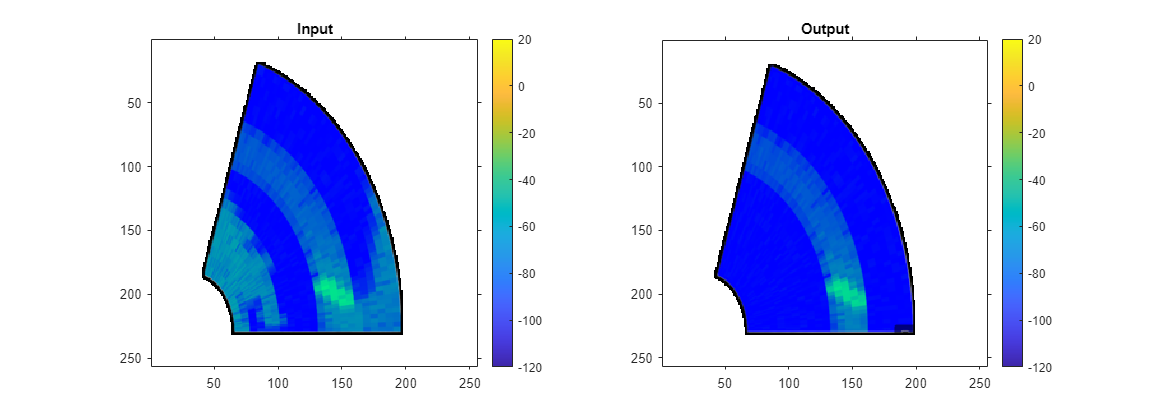

fh = figure;
    fh.Color = 'white';
    
    subplot(1,2,1)
    image = imgs_train(:,:,:,140);
    % Find pixels where all RGB values are 0\
    black_pixels = all(image == 0, 3);
    
    % Create a mask for replacing black pixels
    mask = cat(3, black_pixels, black_pixels, black_pixels);
    
    % Replace black pixels with 1 1 1
    image(mask) = 1;

    imshow(image);
    clim([-120 20])
    colorbar
    axis on
    axis equal
    axis tight
    title('Input')
    
    subplot(1,2,2)
    image = resps_train(:,:,:,140);
    % Find pixels where all RGB values are 0\
    black_pixels = all(image == 0, 3);
    
    % Create a mask for replacing black pixels
    mask = cat(3, black_pixels, black_pixels, black_pixels);
    
    % Replace black pixels with 1 1 1
    image(mask) = 1;
    imshow(image);
    clim([-120 20])
    colorbar
    axis on
    axis equal
    axis tight
    title('Output')
    fh.Position = fh.Position + [0 0 600 0];

imageSize = [256 256 3];
pixelRange = [-4 4];
imageAugmenter = imageDataAugmenter( ...
    RandXReflection=true, ...
    RandXTranslation=pixelRange, ...
    RandYTranslation=pixelRange);
augimdsTrain = augmentedImageDatastore(imageSize,imgs_train,resps_train, ...
    DataAugmentation=imageAugmenter, ...
    OutputSizeMode="randcrop");

layers = unitGenerator(imageSize,NumResidualBlocks=5, ...
   NumSharedBlocks=3);

analyzeNetwork(layers)

miniBatchSize = 128;
learnRate = 0.1;
valFrequency = floor(size(imgs_train,4)/miniBatchSize);
options = trainingOptions("sgdm", ...
    InitialLearnRate=learnRate, ...
    MaxEpochs=80, ...
    MiniBatchSize=miniBatchSize, ...
    VerboseFrequency=valFrequency, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationData={imgs_val,resps_val}, ...
    ValidationFrequency=valFrequency, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=60);

disp(layers);

  dlnetwork with properties:

         Layers: [9×1 nnet.cnn.layer.Layer]
    Connections: [8×2 table]
     Learnables: [152×3 table]
          State: [0×3 table]
     InputNames: {'inputSource'  'inputTarget'}
    OutputNames: {'decoderSourceBlock/out1'  'decoderSourceBlock/out2'  'decoderTargetBlock/out1'  'decoderTargetBlock/out2'}
    Initialized: 1

  View summary with summary.



[net,info] = trainNetwork(augimdsTrain,layers,options);

Error using trainNetwork
Layers argument must be an array of layers or a layer graph.

[YValPred,probs] = classify(net,XVal);

Unrecognized function or variable 'net'.

validationError = mean(YValPred ~= TValidation);
YTrainPred = classify(net,XTrain);
trainError = mean(YTrainPred ~= TTrain);
disp("Training error: " + trainError*100 + "%")
disp("Validation error: " + validationError*100 + "%")